Call the ROC script

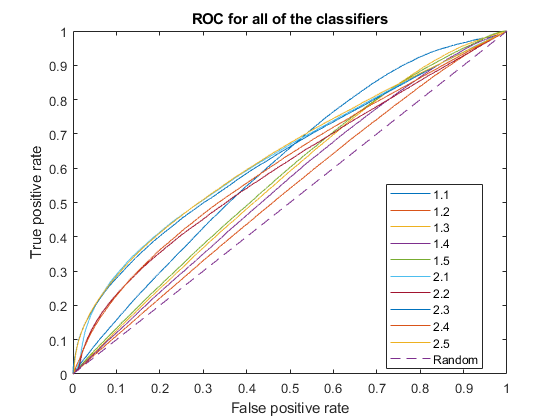

AUC11 = 0.6106

AUC12 = 0.5295

AUC13 = 0.5666

AUC14 = 0.5513

AUC15 = 0.5713

AUC21 = 0.6368

AUC22 = 0.5992

AUC23 = 0.6331

AUC24 = 0.6085

AUC25 = 0.6399

roc_v7_second_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9843

ans = 157

ans = 0.9892

ans = 0.0114

ans = 0.9892

ans = 0.7546

ans = 0.8961

Classifier 2

ans = 0.9793

ans = 159

ans = 0.7295

ans = 0.2537

ans = 0.7295

ans = 0.8287

ans = 0.8657

Classifier 3

ans = 0.9963

ans = 160

ans = 0.9311

ans = 0.0815

ans = 0.9311

ans = 0.8068

ans = 0.8943

Classifier 4

ans = 0.9865

ans = 162

ans = 0.8604

ans = 0.1491

ans = 0.8604

ans = 0.8320

ans = 0.8938

Classifier 5

ans = 0.9878

ans = 151

ans = 0.9231

ans = 0.0735

ans = 0.9231

ans = 0.7517

ans = 0.8467

Classifier 6

ans = 0.0347

ans = 46

ans = 0.9978

ans = 0.0024

ans = 0.9978

ans = 0.1361

ans = 0.3420

Classifier 7

ans = 0.0020

ans = 34

ans = 0.9815

ans = 0.0168

ans = 0.9815

ans = 0.1078

ans = 0.2429

Classifier 8

ans = 0.0013

ans = 33

ans = 0.9967

ans = 0.0032

ans = 0.9967

ans = 0.0848

ans = 0.2583

Classifier 9

ans = 0.0016

ans = 53

ans = 0.9831

ans = 0.0171

ans = 0.9831

ans = 0.1947

ans = 0.3559

Classifier 10

ans = 9.1246e-06

ans = 43

ans = 0.9973

ans = 0.0024

ans = 0.9973

ans = 0.1239

ans = 0.3200

Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val = 0.9978

ind = 6

Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom = 0.1641

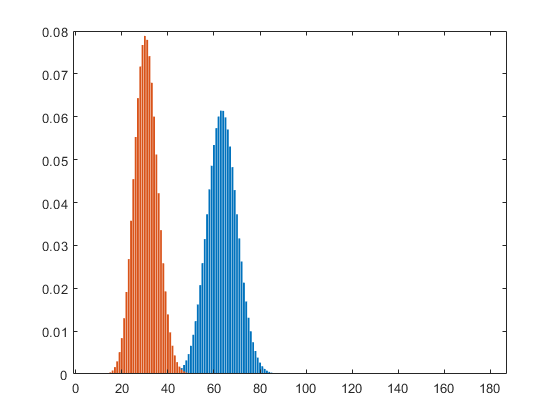

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors = 1.1569

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end
cost = cost * 521

cost = 135981

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 17.0530

Save results

save('./results_characterization/v7_second_op_2.mat','selectedPoints');